# Data Acq

clc
clear
t = 20;                         % Acquire data for 10 seconds
filename = '..\..\..\data_WearableSystem\16module_empty_check\data_23';      % Data file name
% filename = 'train_data_test1';      % Data file name

delete(instrfindall);
sipm_power_ctl_port = 'COM4';
analog_positive_power_ctl_port = 'COM5';
analog_negative_power_ctl_port = 'COM6';

data_acq = 1;      % 如果只是分析数据，可以把这个置0,不重新采集数据
init_one_node = 0; % 初始化第一块节点类型，只想用第一块板子的时候把这个置为1，不能跟init_all_node同时为1
init_all_node = 1; % 初始化所有板子节点类型，想用多块板子的时候把这个置为1， 不能跟init_one_node同时为1
turn_off_power = 0;       % 关闭模拟板电源和传感器电源
train_data_err_check = 1; % 仅空车数据检查可用

if turn_off_power == 1 
    % Set dcpower as remote control mode
    dcpower_set_as_remote_mode(analog_positive_power_ctl_port);
    dcpower_set_as_remote_mode(analog_negative_power_ctl_port);
    dcpower_set_as_remote_mode(sipm_power_ctl_port);
    
    dcpower_set_output_off(sipm_power_ctl_port);
    dcpower_set_output_off(analog_negative_power_ctl_port);
    dcpower_set_output_off(analog_positive_power_ctl_port);
end

if data_acq == 1
%     op = '..\PiModule\host\sw\dist\picopet\picopet.exe';
    op = '..\sw\dist\picopet\picopet.exe';
    trgt = '0x0000';
    
    %pin
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    
        if init_one_node == 1
            % Node ID: 0x00 Node Type: 0x00
            system([op ' -c 0x0002 ' trgt ' 0x00000100']);
        end
        
        % 下面这段是初始化所有节点的，可能有bug,因为python程序还没完全开发好
        % 在1,2两条命令后加足够长的延时应该可以工作，不行就增大延时
        if init_all_node == 1
            trgt = '0xC000';
            system([op ' -c 0x0002 ' trgt ' 0x00000000']);    % 1
            pause(20);
            % 这里需要延时10s 你查下matlab的延时函数，我忘记了
            trgt = '0x000e'; % 假设有4块板子级联，这里就写3，有8块就写7
            system([op ' -c 0x0002 ' trgt ' 0x0000020e']);    % 2
            pause(5);
            % 延时2s
            % pin最后一块板子，pin成功代表初始化成功
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
        end
        
    % 开始采集
    system([op ' -a ' num2str(t) ' -o ' filename '.dat']);
end

2018-09-03 10:43:45,437 INFO [S] 0x0001 0x0000 0x00000000 
2018-09-03 10:43:45,638 INFO [R] 0x8001 0x0000 0x00000000 


2018-09-03 10:43:45,936 INFO [S] 0x0001 0x0000 0x00000000 
2018-09-03 10:43:46,138 INFO [R] 0x8001 0x0000 0x00000000 


2018-09-03 10:43:46,421 INFO [S] 0x0001 0x0000 0x00000000 
2018-09-03 10:43:46,624 INFO [R] 0x8001 0x0000 0x00000000 


2018-09-03 10:43:46,898 INFO [S] 0x0001 0x0000 0x00000000 
2018-09-03 10:43:47,099 INFO [R] 0x8001 0x0000 0x00000000 


2018-09-03 10:43:47,397 INFO [S] 0x0001 0x0000 0x00000000 
2018-09-03 10:43:47,598 INFO [R] 0x8001 0x0000 0x00000000 


2018-09-03 10:43:47,913 INFO [S] 0x0002 0xC000 0x00000000 
2018-09-03 10:43:51,930 WARNING Controller Unit is not responding. Try again or restart. 
2018-09-03 10:43:51,930 WARNING Controller Unit is replying with zeros. 
2018-09-03 10:43:51,930 INFO [R] 0x0000 0x0000 0x00000000 


2018-09-03 10:44:12,290 INFO [S] 0x0002 0x000E 0x0000020E 
2018-09-03 10:44:12,694 INFO [R] 0x8002 0x000E 0x0000020E 


2018-09-03 09:14:41,187 INFO [S] 0x0001 0x000E 0x00000000 
2018-09-03 09:14:41,591 INFO [R] 0x8001 0x000E 0x00000000 


2018-09-03 09:14:41,875 INFO [S] 0x0001 0x000E 0x00000000 
2018-09-03 09:14:42,278 INFO [R] 0x8001 0x000E 0x00000000 


2018-09-03 09:14:42,545 INFO [S] 0x0001 0x000E 0x00000000 
2018-09-03 09:14:42,947 INFO [R] 0x8001 0x000E 0x00000000 


2018-09-03 09:14:43,239 INFO [S] 0x0001 0x000E 0x00000000 
2018-09-03 09:14:43,640 INFO [R] 0x8001 0x000E 0x00000000 


2018-09-03 09:14:43,908 INFO [S] 0x0001 0x000E 0x00000000 
2018-09-03 09:14:44,311 INFO [R] 0x8001 0x000E 0x00000000 


2018-09-03 09:14:44,993 INFO Starting qusb data acquisition... 

19s remaining.
18s remaining.
17s remaining.
16s remaining.
14s remaining.
13s remaining.
12s remaining.
11s remaining.
10s remaining.
9s remaining.
8s remaining.
7s remaining.
6s remaining.
5s remaining.
3s remaining.
2s remaining.
1s remaining.2018-09-03 09:15:04,868 INFO Done acquisition... Emptying buffers... 
2018-09-03 09:15:04,999 INFO QUSB rate is 45.292 MB/s 
2018-09-03 09:15:04,999 INFO Stopping qusb data stream... 
2018-09-03 09:15:04,999 INFO QUSB data stream has stopped. 
2018-09-03 09:15:04,999 INFO Stopping qusb data queue [7]... 
2018-09-03 09:15:05,088 INFO QUSB data queue has stopped. 
2018-09-03 09:15:05,088 INFO 18.961 MB/s written to disk, ..\..\..\data_WearableSystem\16module_empty_check\data_22.dat 


# Analysis

fid=fopen([filename '.dat'],'rb');
% fid=fopen(['.\data\' filename '.dat'],'rb');
raw = fread(fid,'uint8');
fclose(fid);
raw = raw(4001:end);
data = reshape(raw,4,length(raw)/4)';
% data = data(1:100000,:);

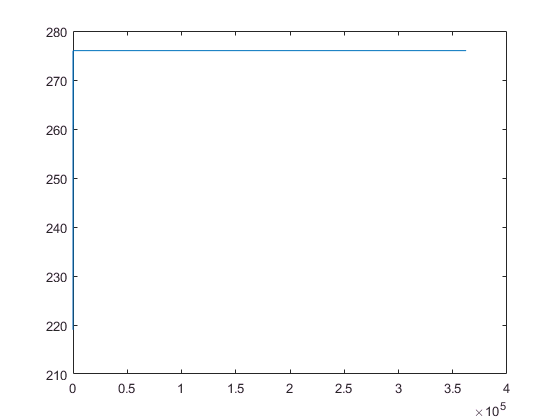

train_head_8bit = 254;
train_end_8bit = 253;
p1 = find(data(:,4) == train_head_8bit);
p2 = p1 + 1;
if  max(p2) > length(data)
    p2 = p2(1:end - 1);
end
train_head_index = p2((data(p2,4) == train_head_8bit) & (data(p2,1) == 0) & (data(p2,2) == 0) &(data(p2,3) == 0));  %%可能会受到TDC的高位计数为254的影响
train_cnt = length(train_head_index);
train_len = diff(train_head_index);
figure;plot(train_len);

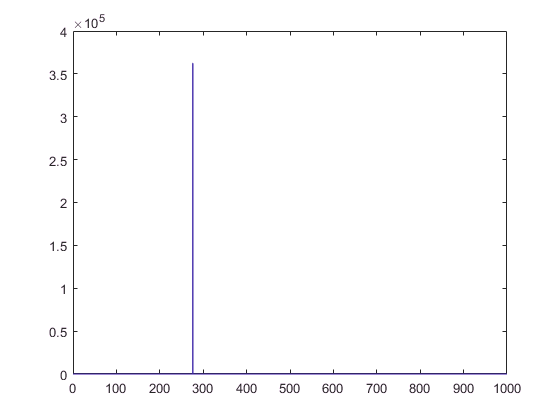

figure;hist(train_len,0:1:1000);xlim([0 1000]);

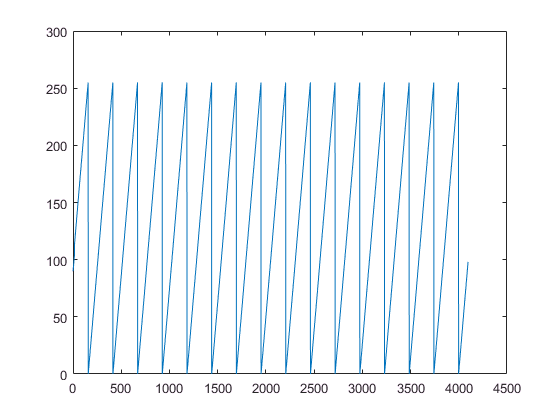

A2=unique(train_len);
n=histc(train_len,A2);
n1=[A2,n];
train_num = data(train_head_index - 1, 2);
figure;plot(train_num(1:4096));

c_train_len = 276;
p1 = find(train_len == c_train_len);
complet_train_head_index = train_head_index(p1) - 1;

complet_train_cnt = length(complet_train_head_index);

train_data = zeros(complet_train_cnt * c_train_len,4);
head_index = 1 : c_train_len : c_train_len * complet_train_cnt;
head_index = head_index';
for i = 0 : 1 : c_train_len - 1
    train_data(head_index + i,:) = data(complet_train_head_index + i,:);
end

single_event_num = train_data(find(train_data(:,4)==240),2); % 提取每节车厢的sigle event数
% mod(single_event_num,2);
find(mod(single_event_num,2) ~= 0);

train_data_err = 0

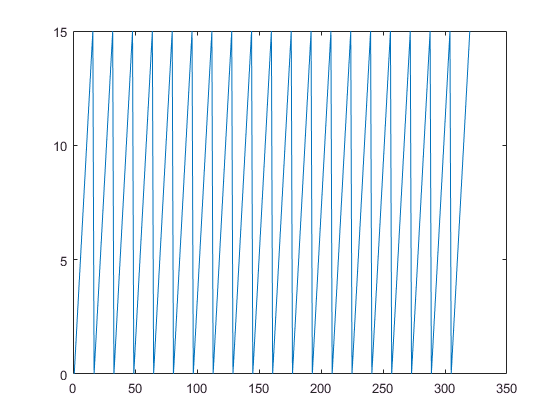

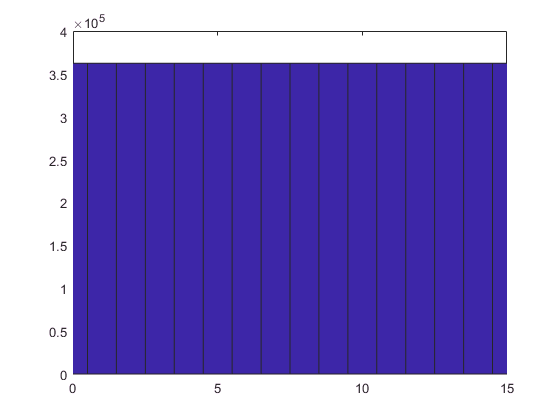

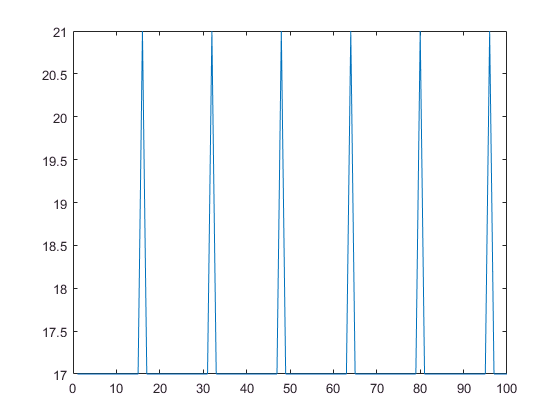

if train_data_err_check == 1
    load train_data_template.mat;
    train_data_err = 0;
    for i= 1:length(head_index)
        train_data_template(1,2) = train_data(head_index(i),2);
        train_data_template(275,2) = train_data(head_index(i),2);
        
        train_data_check = train_data(276*(i-1)+1 : 276*(i-1)+276,:) - train_data_template;
        train_data_err = train_data_err + length(find(train_data_check~= 0));
    end
    train_data_err
    
    p1 = find(train_data(:,4) == 240);
    p2 = p1(18:end) - 17;
    coach_end_index = p1(train_data(p2,4) == 240 | (train_data(p2,4) == 254 & train_data(p2 - 1,4) == 254));
    coach_id = mod(train_data(coach_end_index,3),128);
    figure;plot(coach_id(961:1280));
    figure;hist(coach_id,0:1:15);xlim([0 15]);
    coach_len = diff(coach_end_index);
    figure;plot(coach_len(1:100));
end